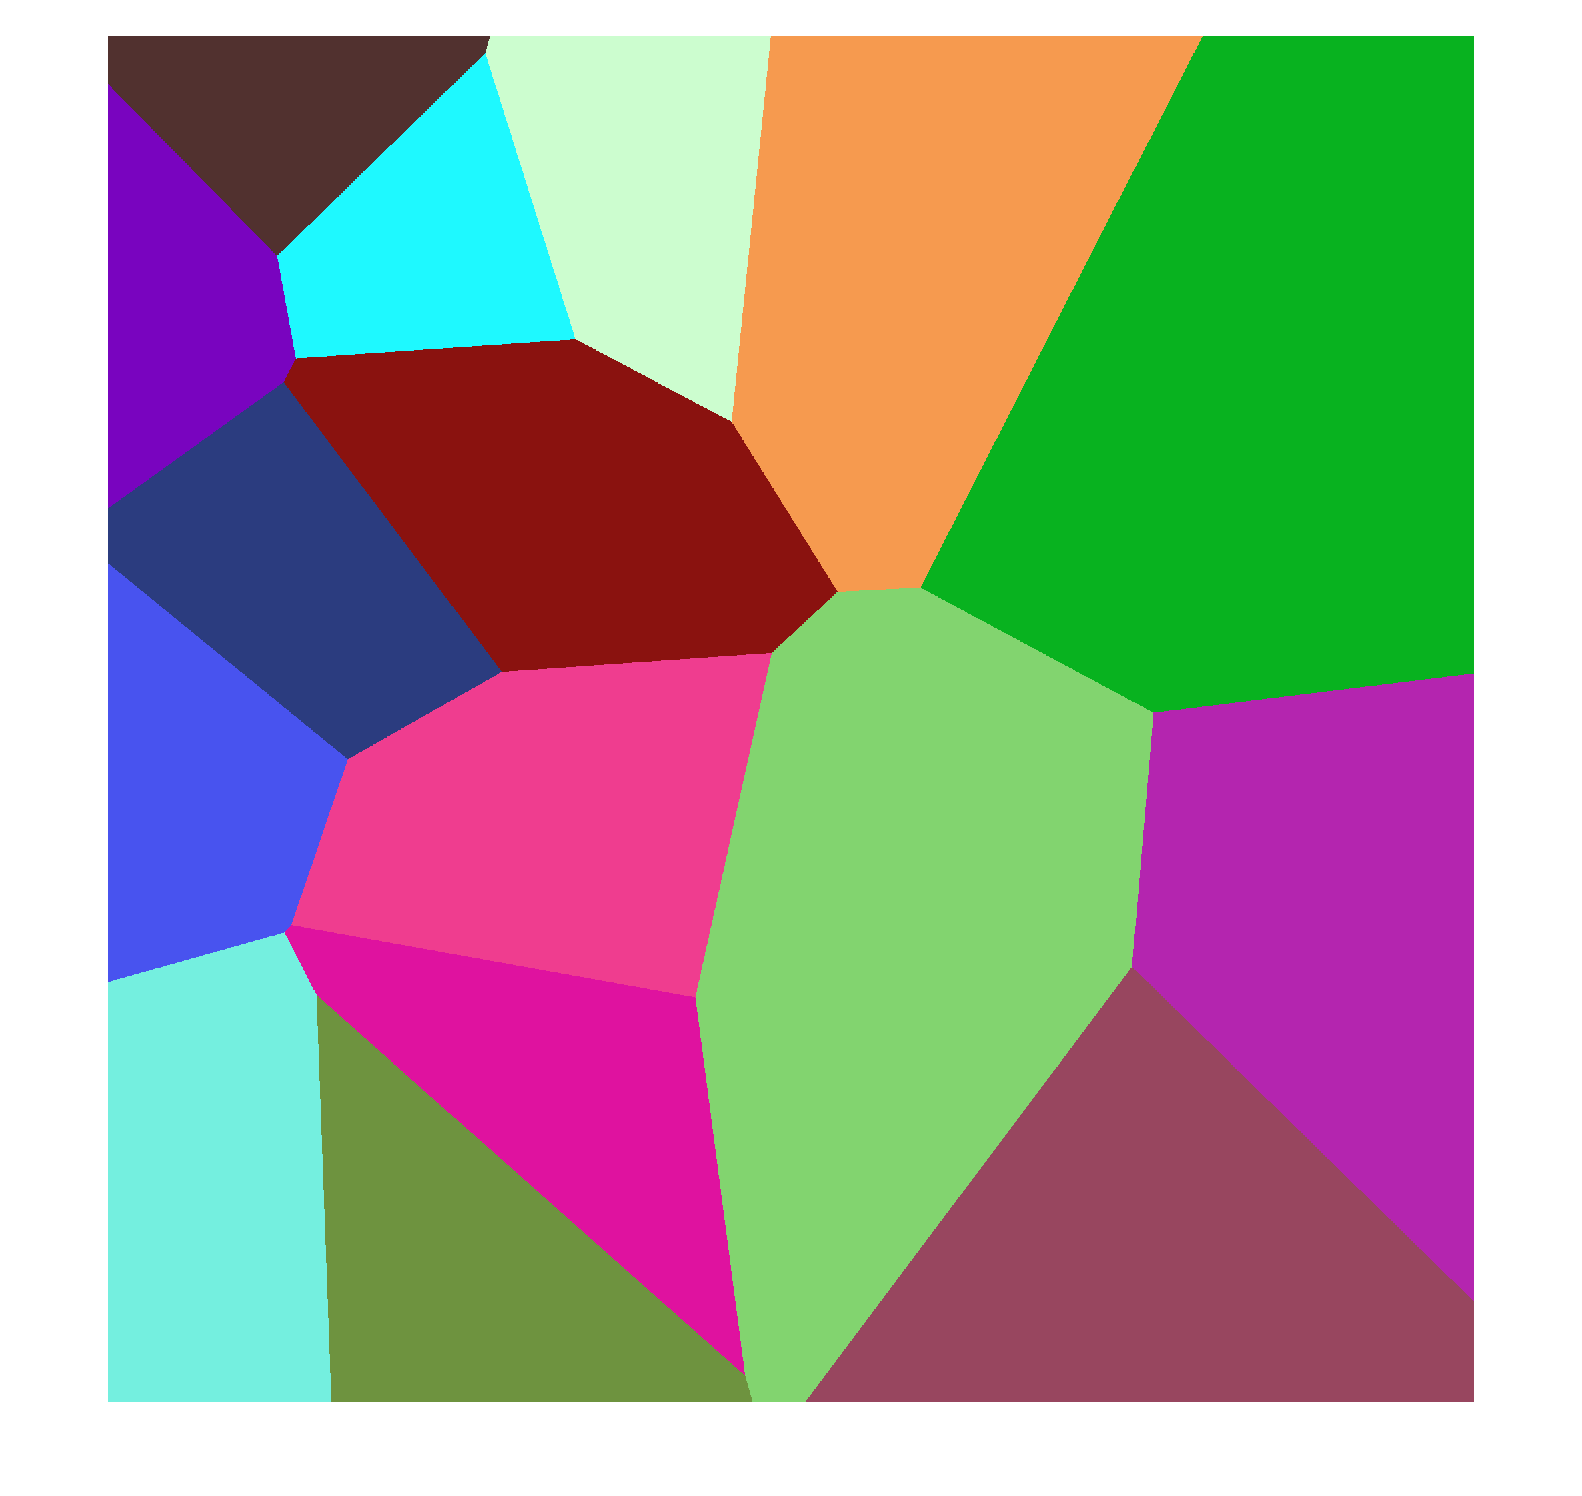

clear all
clc

N=256;
P=16;
x=zeros(N);
x(:,:,2)=zeros(N);
x(:,:,3)=zeros(N);
coordenadasRandom =  randi([1, N], [P,2]);

color=256/P;

for i = 1:N
    for j = 1:N
        temp = [N,1];
        for k = 1:P
            d = sqrt((i-coordenadasRandom(k,1))^2+(j-coordenadasRandom(k,2))^2);
            if d==0
                temp = [d,k];
                break
            elseif temp(1)<d
                continue
            else
                temp = [d,k];
            end
        end
        q=uint8(temp(2));
        r=mod(coordenadasRandom(q,1),256);
        g=mod(coordenadasRandom(q,2),256);
        x(i,j,:)=[r,g,temp(2)*color-1];
    end
end

imshow(uint8(x))

imwrite(uint8(x),"voronoi2048pp.jpg")